# Apply Model to Many Letters

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Making a Model for 13 Letters

You now have a simple two-feature model that works well for three particular letters (J, M, and V). Could this model also work for the whole alphabet? In this interaction, you will create and test the same kNN model as before, but for 13 letters (half the English alphabet).

Do not edit. This code loads the data.

clear;clc
load letterfeatures.mat
traindata

traindata = 2906×26 table
    AspectRatio      MADX       MADY        AvgU       MADU         AvgV        MADV      CorrXY       CorrXP      CorrXU      CorrXV      CorrYP       CorrYU      CorrYV       CorrPU       CorrPV       CorrUV      NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    ________    _______    ________    _______    __________    ______    ___

testdata

testdata = 968×26 table
    AspectRatio     MADX       MADY        AvgU        MADU        AvgV       MADV      CorrXY      CorrXP       CorrXU       CorrXV       CorrYP       CorrYU        CorrYV       CorrPU      CorrPV       CorrUV     NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    _______    _______    _________    _______    ________    ______    _______

The MAT-file `featuredata13letters.mat` contains a table (`features`) of the same features as before. However, now the data includes samples of 13 different letters.

## Task 1

Use the `gscatter` function to plot the observations in `features`, with aspect ratio on the horizontal axis and duration on the vertical axis, colored by class (stored in the `Character` variable).

The axis limits will not be evaluated, but you might want to experiment with the limits to zoom in on the bulk of the observations.

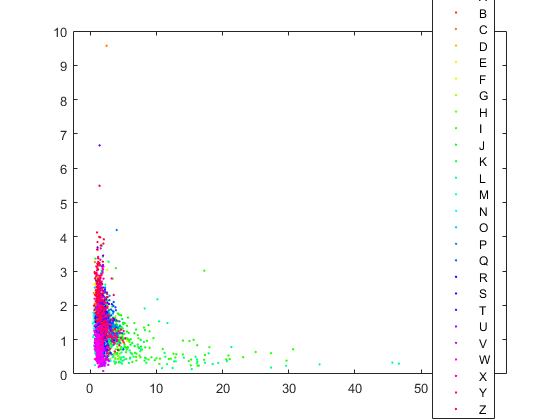

gscatter(traindata.AspectRatio,traindata.MADU,traindata.Character)

% xlim([0 10])

## Task 2

Use the `fitcknn` function to fit a model to the data. Set the `"NumNeighbors"` property to 5. Store the model in a variable called `knnmodel`. Use the model to predict the classes for the observations stored in `testdata`. Store the predictions in a variable called `predictions`.

knnmodel = fitcknn(traindata,"Character",'NumNeighbors',5);
predictions = predict(knnmodel,testdata);

The table `testdata` contains the known classes in the variable `Character`.

## Task 3

Calculate the misclassification rate of the model and create a confusion chart. Store the misclassification rate in a variable called `misclass`.

misclass=sum(predictions~=testdata.Character)/numel(predictions)

misclass = 0.2324

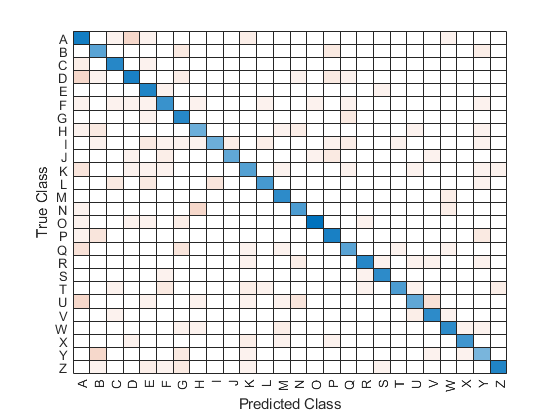

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [26×26 double]
         ClassLabels: [26×1 categorical]

  Show all properties


confusionchart(testdata.Character,predictions)

## Further Practice

Not surprisingly, a model with only two features (chosen to distinguish three particular letters) does not generalize well to many letters. In the following sections you will learn how to engineer more features and build better models.